Запасы по амплитуде и по фазе

ww = 10.^(-2:0.01:4);
sww = 1i*ww;

syms Tu_s s Cm_s J_s b_0 b_1 b_2 a_1

Wtfobsp = 1/((Tu_s)*s + 1)*Cm_s/J_s/s;
Wsplp = (b_2*s^2 + b_1*s + b_0)/(a_1*s + 1)/s;

Wol_symbolic = Wtfobsp*Wsplp

$$Wol\_symbolic = \frac{{\mathrm{Cm}}_{s}\,\left(b_{2}\,s^{2}+b_{1}\,s+b_{0}\right)}{J_{s}\,s^{2}\,\left({\mathrm{Tu}}_{s}\,s+1\right)\,\left(a_{1}\,s+1\right)}$$

load('var_30.mat')
To = 0.001;
J = 0.0012;
Tt = 0.003;
Tz = To/2 + To/1000;
Tu = Tt + Tz;

rp.poles = -[551-236*j 551+236*j 288-554*j 288+554*j];
rp.poly = poly(rp.poles);
r3 = rp.poly(2);
r2 = rp.poly(3);
r1 = rp.poly(4);
r0 = rp.poly(5);

b2 = ((J*Tu^2)/(Cm*(Tu*r3 - 1)))*r2 - J/Cm;
b1 = (J*Tu^2*r1)/(Cm*(Tu*r3 - 1));
b0 = (J*Tu^2*r0)/(Cm*(Tu*r3 - 1));
a1 = Tu/(Tu*r3 - 1);

Wol_numeric = Cm.*((b2.*sww.^2+b1.*sww+b0))./(J.*sww.^2.*(Tu.*sww + 1).*(a1.*sww + 1));

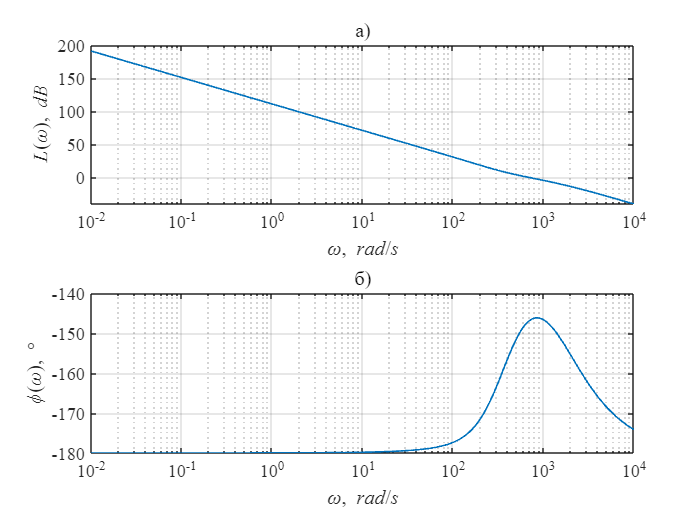

[LL, phiphi] = freqplot(ww,Wol_numeric);

Графики ЛАЧХ (а) и ФЧХ (б) ПФ разомкнутой системы.

[Lminmin, indind] = min(abs(LL));
phi_marg = phiphi(indind) - (-180);
fprintf('Запас по фазе: %.3f%c при частоте %.3f рад/c\n',phi_marg,char(176),ww(indind))

Запас по фазе: 33.019° при частоте 691.831 рад/c


#### Показатель колебательности

Wcl_symbolic = collect(Wol_symbolic./(1 + Wol_symbolic),s)

$$Wcl\_symbolic = \frac{\left({\mathrm{Cm}}_{s}\,b_{2}\right)\,s^{2}+\left({\mathrm{Cm}}_{s}\,b_{1}\right)\,s+{\mathrm{Cm}}_{s}\,b_{0}}{\left(J_{s}\,{\mathrm{Tu}}_{s}\,a_{1}\right)\,s^{4}+\left(J_{s}\,a_{1}+J_{s}\,{\mathrm{Tu}}_{s}\right)\,s^{3}+\left(J_{s}+{\mathrm{Cm}}_{s}\,b_{2}\right)\,s^{2}+\left({\mathrm{Cm}}_{s}\,b_{1}\right)\,s+{\mathrm{Cm}}_{s}\,b_{0}}$$

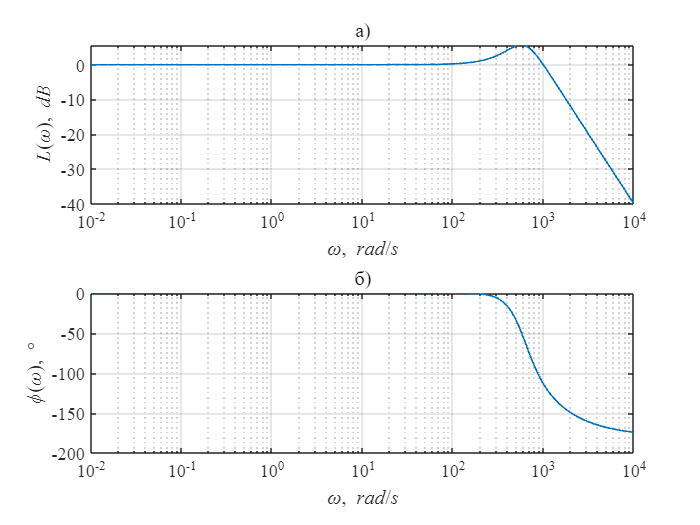

Wcl_numeric = Wol_numeric./(1 + Wol_numeric);

[LL,phiphi] = freqplot(ww,Wcl_numeric);

Графики АЧХ (а) и ФЧХ (б) ПФ замкнутой системы.

Показатель колебательности

MM = 10^((max(LL)-LL(1))/20)/10^(LL(1)/20);
fprintf('Показатель колебательности M: %.3f \n',MM)

Показатель колебательности M: 1.924 
